optimParams_v1

Optim Params by using Surrogate optimization for an expensive optimization problems

% Load data
% load pricevolumedata.mat ;
dataInput = load("pricevolumedata.mat")

dataInput = struct with fields:
    closepriceTT: [1212×665 timetable]
     highpriceTT: [1212×665 timetable]
      indexclean: [1212×6 timetable]
      lowpriceTT: [1212×665 timetable]
     openpriceTT: [1212×665 timetable]
        volumeTT: [1212×665 timetable]


% Test objective and constraints function
% counter help  = [1    2   3   4   5   6   7   8   9   10  11]
paramsInput     = [70	106	5	3	8	14	107	29	4	4	6]

paramsInput =     70   106     5     3     8    14   107    29     4     4     6


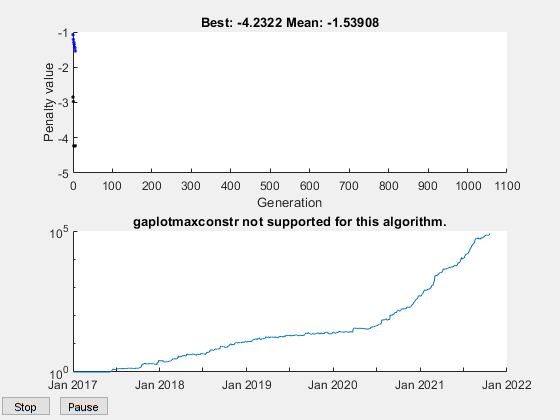

portEndValue = 8.1092e+04

portMinValue = 1

portMaxValue = 8.1092e+04

MaxDD = 0.1617

MaxDDIndex =    253
   271


drawdownDate = 2×1 datetime array
   2017-12-28
   2018-01-23


sharpeRatio = 4.7270

FortValueAtOptPoint = 27.2284

PortRetOptPtEnd = 2.9772e+03

optimPointDate = datetime
   2020-02-25


nYear = 4.8027

CAGR = 9.5225

dailyRetAvg = 0.0099

dailyRetMin = -0.1234

dailyRetMax = 0.3212

symCumRetEndT = 665×2 table
     symbol     Cumulative Return
    ________    _________________

    {'FIRE'}     {[1.5254e+15]}  
    {'INAF'}     {[5.3072e+12]}  
    {'ABBA'}     {[3.6291e+12]}  
    {'DEAL'}     {[2.6419e+10]}  
    {'JSKY'}     {[2.2533e+10]}  
    {'BBHI'}     {[5.2116e+09]}  
    {'ESSA'}     {[1.9855e+09]}  
    {'FILM'}     {[2.2483e+08]}  
    {'DMMX'}     {[2.0397e+08]}  
    {'POLL'}     {[9.6005e+07]}  
    {'FREN'}     {[9.5931e+07]}  
    {'KOTA'}     {[8.6604e+07]}  
    {'JAST'}     {[6.3205e+07]}  
    {'AGRO'}     {[4.1083e+07]}  
    {'MARK'}     {[3.6404e+07]}  
    {'MPPA'}     {[2.6861e+07]}  


CAGR = 9.5225

tradingSignalTT = tradingSignalFcn_v1 (paramsInput, dataInput) ;
portDailyRetTT = tradingBacktestFcn_v1 (tradingSignalTT, dataInput) ;

CAGR = analyzeTradeResults (dataInput, tradingSignalTT, portDailyRetTT, optimPoint)

Optim parameters

Define upper, lower bound and constraints

startTime = tic;
% Define upper, lower and bound 
% counter help  = [1    2   3   4   5   6   7   8   9   10  11]
lb              = [20   50  5   1   3   2   80  10  1   1   0] ;
ub              = [150  150 60  6   20  30  250 60  10  8   15] ;

% lb              = [60   50  5   1  2   0   60  5   3   1   0] ;
% ub              = [250  200 60  10 10  15  250 30  5   5   8] ;

% Input parameters
% volumeMAtreshold = x(1)/100 ; % input #1 
% volumeMAlookback = x(2) ; % input #2
% valueThreshold = x(3)*10^9 ; % input #3 in Rp billion
% valueLookback = x(4) ; % input #4
% volumeValueBufferDays = x(5) ; % input #5
% priceRetLowCloseThresh = x(6)/100 ; % input #6
% priceMAThreshold = x(7)/100 ; % input #7
% priceMAlookback = x(8) ; % input #8
% priceVolumeValueBufferDays = x(9) ; % input #9
% cutlossLookback = x(10) ; % input #10
% cutlosspct = x(11)/100 ; % input #11 


% Integer constraints
nvars = 11 ;
intcon = 1:nvars ;


% Objective & constraints function
optimPoint = 400

optimPoint = 400

dataInput = load("pricevolumedata.mat") ;

ObjectiveFunction =  @(x)objFcn(x, dataInput, optimPoint);

ConstraintFunction = @(x)nlconstFcn(x, dataInput, optimPoint);

% Set options
% maxFcnEval = 400;
opts = optimoptions('ga','MaxStallGenerations',50,'FunctionTolerance',1e-2,...
    'MaxGenerations',300,'PlotFcn',@gaplotbestfun, "UseParallel", true);

% options = optimoptions("ga",'PlotFcn',{@gaplotbestf,@gaplotmaxconstr}, ...
%     'Display','iter', "UseParallel", true, "UseVectorized",false);


Call `surrogateopt` to solve the problem


                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200          -2.974          -1.212        0
    2              295          -4.232          -1.294        0
    3              390          -4.232          -1.343        1
    4              485          -4.232          -1.428        2
    5              580          -4.232          -1.452        3
    6              675          -4.232          -1.539        4
    7              770          -5.003          -1.549        0
    8              865           -5.82          -1.556        0
    9              960          -8.088          -1.762        0
   10             1055          -13.16          -2.122        0
   11             1150          -18.71          -2.476        0
   12             1245          -18.71          -2.442        1
   13             1340          -18.71          -2.962        2
   14             1435        

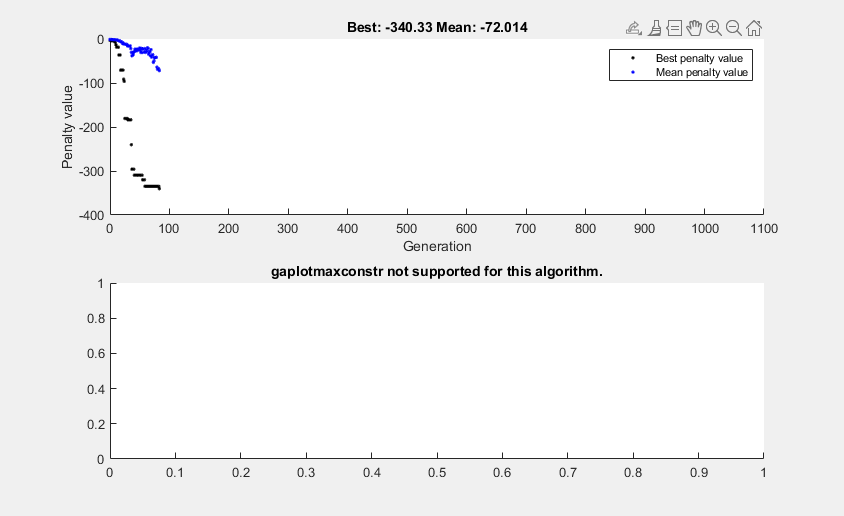

Optimization terminated: stop requested from plot function.


x =     40    51     5     1    11     2   139    49     7     6     8


fval = -340.3299

% Call surrogateopt to solve the problem
rng default % For reproducibility
[x,fval] = ga(ObjectiveFunction,nvars,[],[],[],[],lb,ub, ...
    ConstraintFunction, intcon,options)

sol = x;

totalTime = toc(startTime)

totalTime = 2.5511e+03

Examine result of optimized params

paramsInput     = sol

paramsInput =     40    51     5     1    11     2   139    49     7     6     8


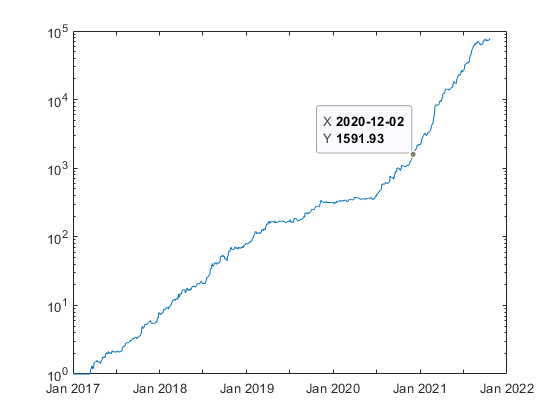

portEndValue = 7.9240e+04

portMinValue = 1

portMaxValue = 7.9240e+04

MaxDD = 0.1945

MaxDDIndex =    444
   458


drawdownDate = 2×1 datetime array
   2018-09-21
   2018-10-11


sharpeRatio = 5.3831

FortValueAtOptPoint = 340.3299

PortRetOptPtEnd = 231.8316

optimPointDate = datetime
   2020-02-25


nYear = 4.8027

CAGR = 9.4720

dailyRetAvg = 0.0098

dailyRetMin = -0.0876

dailyRetMax = 0.1552

symCumRetEndT = 665×2 table
     symbol     Cumulative Return
    ________    _________________

    {'TKIM'}     {[2.1014e+48]}  
    {'DMMX'}     {[5.8119e+34]}  
    {'DEAL'}     {[3.5863e+26]}  
    {'INKP'}     {[8.4663e+25]}  
    {'INDY'}     {[5.5763e+25]}  
    {'ASSA'}     {[3.7741e+24]}  
    {'MARI'}     {[9.6288e+22]}  
    {'IMAS'}     {[2.7272e+22]}  
    {'MARK'}     {[1.0734e+22]}  
    {'MCAS'}     {[6.1734e+21]}  
    {'BRIS'}     {[3.0885e+20]}  
    {'INAF'}     {[8.7735e+19]}  
    {'MINA'}     {[8.1240e+19]}  
    {'AGRO'}     {[4.3361e+19]}  
    {'FIRE'}     {[2.8626e+19]}  
    {'MAMI'}     {[2.4143e+19]}  


CAGR = 9.4720

tradingSignalTT = tradingSignalFcn_v1 (paramsInput, dataInput) ;
[portDailyRetTT] = tradingBacktestFcn_v1 (tradingSignalTT, dataInput) ;

CAGR = analyzeTradeResults (dataInput, tradingSignalTT, portDailyRetTT, optimPoint)

Analyze the input parameters compared to its boundaries

% Examine result of optimized params
% Input parameters
% volumeMAtreshold = x(1)/100 ; % input #1 
% volumeMAlookback = x(2) ; % input #2
% valueThreshold = x(3)*10^9 ; % input #3 in Rp billion
% valueLookback = x(4) ; % input #4
% volumeValueBufferDays = x(5) ; % input #5
% priceRetLowCloseThresh = x(6)/100 ; % input #6
% priceMAThreshold = x(7)/100 ; % input #7
% priceMAlookback = x(8) ; % input #8
% priceVolumeValueBufferDays = x(9) ; % input #9
% cutlossLookback = x(10) ; % input #10
% cutlosspct = x(11)/100 ; % input #11 

% counter help  = [1    2   3   4   5   6   7   8   9   10  11]
counterhelp     = [1    2   3   4   5   6   7   8   9   10  11]

counterhelp =      1     2     3     4     5     6     7     8     9    10    11


% sol           = [40	51	5	1	11	2	139	49	7	6	8 ];

sol =     40    51     5     1    11     2   139    49     7     6     8


lb              = [20   50  5   1   3   2   80  10  1   1   0 ] 

lb =     20    50     5     1     3     2    80    10     1     1     0


ub              = [150  150 60  6   20  30  250 60  10  8   15] 

ub =    150   150    60     6    20    30   250    60    10     8    15
